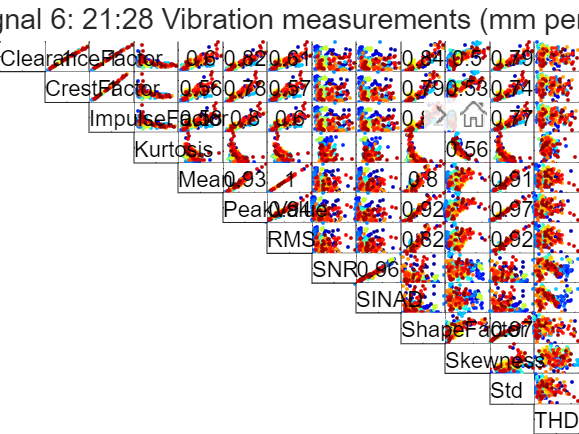

% As an example take feature 5, the Mean, of each signal.
% Plot the mean of each signal against each of the others.
% Compute the R2 value and if it's above 0.3 print the value.
signalNum = 6;
R2 = fnPlotFeatureVsFeature(signalNum, sensorNames, featureNames, signalName, FeaturesAll);

% Print the table of R2 values verse every other signal
% Lower diagonal all 0 because it would just be a mirror image of the top
% triangle
disp(num2str(R2, '%.2f  '));

0.00  1.00  1.00  0.22  0.60  0.82  0.61  0.02  0.01  0.84  0.50  0.79  0.04
0.00  0.00  1.00  0.21  0.56  0.78  0.57  0.02  0.01  0.79  0.53  0.74  0.04
0.00  0.00  0.00  0.22  0.58  0.80  0.60  0.02  0.01  0.82  0.51  0.77  0.04
0.00  0.00  0.00  0.00  0.06  0.12  0.06  0.01  0.01  0.21  0.56  0.17  0.02
0.00  0.00  0.00  0.00  0.00  0.93  1.00  0.04  0.03  0.80  0.06  0.91  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.94  0.03  0.02  0.92  0.19  0.97  0.03
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.04  0.03  0.82  0.06  0.92  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.96  0.02  0.00  0.02  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01  0.00  0.01  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.25  0.97  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.19  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00

% As an example, take the first row
% Signal 1 has an R2 value greater than 0.3 with Signal 2, 7 and 8
% Thus these four signals could form a good mode.
fs = 5; % Sampling frequency 
signalArray = [1, 2, 7, 8]; % Array of correlated signals for models
sig1 = FeaturesAll.(signalName(signalArray(1)) + featureNames(5));
sig2 = FeaturesAll.(signalName(signalArray(2)) + featureNames(5));
sig3 = FeaturesAll.(signalName(signalArray(3)) + featureNames(5));
sig4 = FeaturesAll.(signalName(signalArray(4)) + featureNames(5));

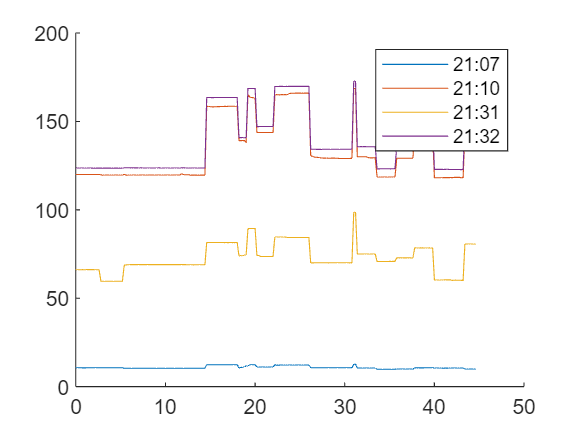

% Plot the identified signals for the Mean of each signal
n = size(sig1, 1); % Sample Size
t = ( 0 : 1/fs : (n / fs) - 1/fs)';
figure(); hold on;
plot(t, sig1);
plot(t, sig2);
plot(t, sig3);
plot(t, sig4);
txt1 = char(sensorNames(signalArray(1)));
txt2 = char(sensorNames(signalArray(2)));
txt3 = char(sensorNames(signalArray(3)));
txt4 = char(sensorNames(signalArray(4)));
leg = legend(txt1(1:5), txt2(1:5), txt3(1:5), txt4(1:5));

% Since there are four signals, let's try some models with three signals
% Keep Signal 3 as output to begin and try 3 candidates with combinations of the
% remaining signals
k = 3; % Number of parameters

% Model candidate 1
% Use Signal 4 as output, 1 and 2 as input
X1 = sig1;
X2 = sig2;
X3 = sig4;

X = [ones(size(X1)) X1 X2];
Y = X3;

beta = lsqr(X, Y);

lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.0075.


Y_est = X * beta;
RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

% From Matlab AIC function
%    'nAIC': Normalized Akaike's Information Criterion (default)
%            nAIC = log(det(E'*E/N)) + 2d/N
%     'AIC': Akaike's Information Criterion (raw measure)
%            AIC = N*nAIC + N*(ny*log(2*pi) + 1)
AIC(1) = -2*(log(RSS)) + 2*k;
AIC2(1) = 2 * k + n * log (RSS / n); % Which is the better equation?

% An alternative formula for least squares regression type analyses 
% for normally distributed errors:
% https://www.statisticshowto.com/akaikes-information-criterion/
deltaAIC(1) = 2 * k + n * log(RSS);

% Fit equation from compare function
FIT = 100 * (1-norm(Y-Y_est)/norm(Y-mean(Y)))

FIT = 93.8789